# Coupled Attitude and Orbit Motion using Cowell's formulation and quaternions

## note

## references 

## revisions

since 2022  y.yoshimura, y.yoshimula@gmail.com, y.yoshimura.a64@m.kyushu-u.ac.jp

clc
clear
close all

## constants and satellite parameters

const = orbitConst; % for orbital motion
earthVSOP = vsopConst; % for earth orientation

% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname); % earth oriented parameters (EOP)

model = 3 % 1: symmetric flat plate, 2: box-wing, 3: GEO sat

model = 3


if model == 1
    objName = 'flatPlate.obj';    
    sat = readSC(objName); % satellite shape and optical parameters

    sat.MOI = diag([10, 15, 20]); % moment of inertia, kgm^2
    sat.m = 50; % mass, kg
    
elseif model == 2 % box-wing 
    objName = 'boxWing.obj';
    sat = readSC(objName);

    sat.MOI = diag([45, 50, 60]); % moment of inertia, kgm^2
    sat.m = 350; % mass, kg

elseif model == 3 % not yet prepared
    objName = 'geoSat.obj';
    sat = readSC(objName);

    sat.MOI = diag([450, 500, 600]); % moment of inertia, kgm^2
    sat.m = 3500; % mass, kg

else    
    error('invalid model flag');
end

number of vertices:
        3810

number of faces:
        7604



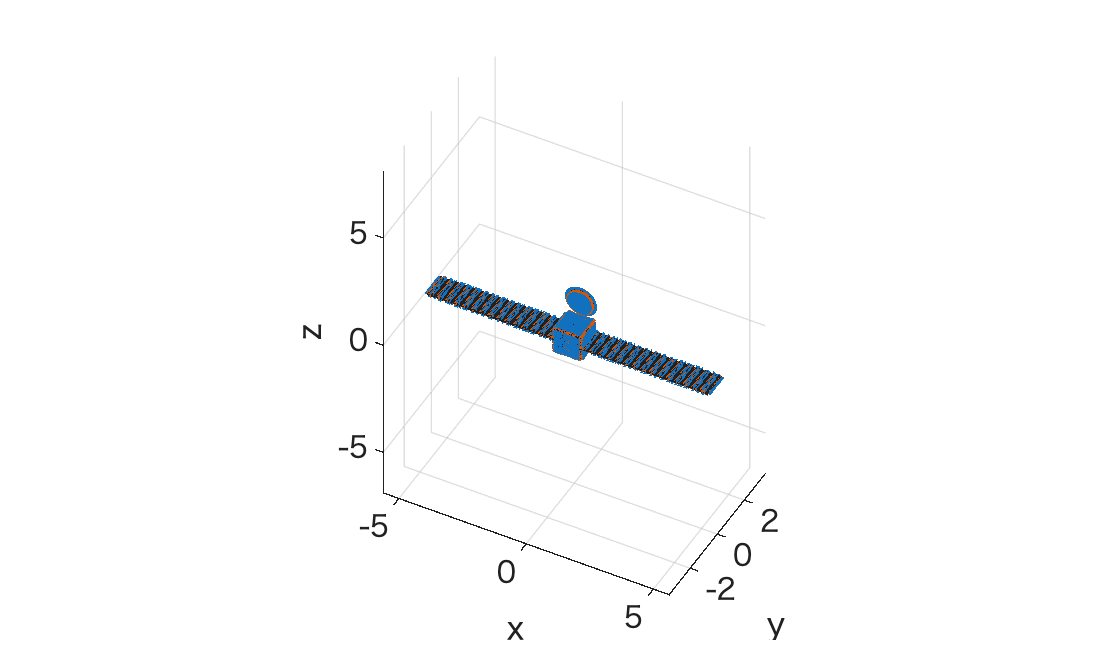


showSC(sat, "Normal", "on") % visualize satellite


% mex化 self-shadowing, if necessary
tmpsun = [0 0 1];
codegen -report selfShadow.mlx -args {sat, tmpsun} % 三角facetと四角facetに応じて作り直さないとダメ

コードの生成が成功しました:レポートの表示



## initial condition


$${\bf x}=[x,y,z,v_x,v_y,v_z, {\bf q}^T, {\bf \omega}^T]^T$$


### attitude

% qIni = zyx2q(4, -1.3222, 1.4059, 0); % initial quaternion, q(4) is the scalar part
qIni = [0 0 0 1];
wIni = deg2rad([0.1, -0.01, -0.3]); % initial angular rate, rad/s

### orbit

tle.oe = $a {\rm [km]}, e,i {\rm [rad]},\Omega {\rm [rad]},\omega{\rm [rad]},M{\rm [rad]}$

trueAnomalyFlag = 1;
tle = readTLE('JCSAT2.txt', const);

[rIni, vIni] = oe2rv(tle.oe, trueAnomalyFlag, const.GE) % at inertial frame, km, km/s

rIni = 1.0e+04 *

    1.9199    3.7540    0.0025


vIni =    -2.7371    1.4006   -0.0022


rIni = rIni .* 10^3; % m
vIni = vIni .* 10^3; % m/s
jd = tle.jd; % Julian day, day
[yy, mm, dd, hh, m, s] = jd2gc(jd);
utc = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)

% initial condition
xIni = [rIni, vIni, qIni, wIni];
tspan = 0:5:60*60*6;


### observer (initial) position

obsLon = deg2rad(130.216544); % longitude, rad
obsLat = deg2rad(33.594649); % latitude, rad
[obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.REm); % observer position@ECEF, m
% dcmITRF2gcrf = itrf2gcrf(utc, leapJD, iau06, eopDataAll);
% qITRF2gcrf = dcm2q(4, dcmITRF2gcrf);
% qGCRF2itrf = dcm2q(4, dcmITRF2gcrf');
% obsECI = qRotation(4, obsPosECEF, qITRF2gcrf); % observer @ECI, m, 1x3 vec.


## ODE

options = odeset('RelTol',1e-9,'AbsTol',1e-9);
[t_, x_] = ode89(@(t,x)eomAttiOrb(t,x,const,sat), tspan, xIni, options);

## data handling

qITRF2gcrf = zeros(length(t_), 4);

jdHistory = tle.jd + s2day(t_); % time history in Julian day
[yy, mm, dd, hh, m, s] = jd2gc(jdHistory);
utc = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)
for ii = 1:length(t_)
    dcmITRF2gcrf = itrf2gcrf(utc(ii), leapJD, iau06, eopDataAll);
    qITRF2gcrf(ii,:) = dcm2q(4, dcmITRF2gcrf);
end

r = x_(:,1:3); % m, position at i-frame
v = x_(:,4:6); % m/s, velocity at i-frame
q = x_(:,7:10); % quaternion w.r.t. inertial frame
w = x_(:,11:13); % rad/s, angular rate  w.r.t. inertial frame
tmp = q2zyx(4, q);
phi = tmp(:,1);
theta = tmp(:,2);
psi = tmp(:,3);

## Sun position and observer position

sunI = sun(jdHistory, const, earthVSOP);
sunI = sunI .* 10^3; % m
sunRel = sunI - r; % relative vec from sat to sun @inertial frame, nx3, m
sunPosB = qRotation(4, normRow(sunRel), q);% sun unit directional vectors @body-fixed frame, nx3

obsECI = qRotation(4, repmat(obsPosECEF,length(jdHistory),1), qITRF2gcrf); % observer position @ECI, nx3 m
obsRel = obsECI - r; % relative vec from sat to observer @inertial frame, nx3, m
obsB = qRotation(4, normRow(obsRel), q); % relative observer directional vectors@inertial frame, nx3,


## Light curve

nu = shadow(r, sunI, const.RSm, const.REm); % calc Earth's shadow
[mApp, ~] = lc(sat, 4, q, r, obsECI, sunI, nu, 'AS'); % relative magnitude

次を使用中のエラー: lc (行 28)
位置 8 の引数が無効です。 名前と値の引数に名前と値の両方が含まれていることを確認してください。

% fObs = magInv(mApp, vecnorm(obsRel,2,2));


## show figs

%% orbit
figure
plot3(r(:,1)./1000, r(:,2)./1000,r(:,3)./1000)
hold on
plot3(obsECI(:,1)./1000, obsECI(:,2)./1000,obsECI(:,3)./1000,'r')
tmp = gmst(jdHistory(end));
drawEarth(tmp, 0.6, const);
xlabel('x km'), ylabel('y km'), zlabel('z km')
axis equal

%% light curve
figure
plot(t_, mApp)
xlabel('time [s]'), ylabel('Light curve, relative magnitude')
set(gca, 'YDir', 'reverse')

%% attitude
figure % quaternion
tFig = tiledlayout(4,1), nexttile
plot(t_,q(:,1),'r'), nexttile
plot(t_,q(:,2),'g'), nexttile
plot(t_,q(:,3),'b'), nexttile
plot(t_,q(:,4),'k')
xlabel(tFig, 'Time [s]')
ylabel(tFig, 'Quaternion ')

figure % attitude angle
plot(t_, rad2deg(phi))
hold on
plot(t_, rad2deg(theta))
plot(t_, rad2deg(psi))
ylabel('\phi, \theta, \psi')
%
% figure % angular rate,
% plot(t_, rad2deg(w(:,1)))
% hold on
% plot(t_, rad2deg(w(:,2)))
% plot(t_, rad2deg(w(:,3)))
% ylabel('angular rate deg/s')


## save (all) variables if necessary

### .mat format

fName = objName(1:end-4); % exclude '.obj'

save(strcat(fName,'.mat'), 't_','mApp','q','phi','theta','psi',...
    'w','r','v','obsECI','jdHistory', 'sat','obsRel','sunI')


### .csv format 

% writematrix(["t", "mApp"; ...
%     t_ mApp], 'lc.csv')
% writematrix(["q1", 'q2', 'q3', 'q4', "phi", "theta", "psi", 'wx', 'wy','wz';...
%     q phi theta psi w],'attitude.csv')
% writematrix(["x", "y", "z", "vx", 'vy', "vz";
%     r, v], 'position.csv')
% writematrix(["obsECIx", "obsECIy", "obsECIz", 'jdHistory', 'obsRelx','obsRely','obsRelz', 'sunPosIx', 'sunPosIy', 'sunPosz'; 
%     obsECI, jdHistory, obsRel, sunPosI], 'info.csv')
% writematrix(["area", 'posx', 'posy','posz','nX','nY','nZ', 'uuX', 'uuY','uuZ','uvX', 'uvY','uvZ','qlb1','qlb2','qlb3','qlb4','Ca', 'Cd', 'Cs', 'nu', 'nv', 'F0'
%     sat.area, sat.pos, sat.normal, sat.uu, sat.uv, sat.qlb, sat.Ca, sat.Cd, sat.Cs, sat.nu, sat.nv, sat.F0],'sat.csv');
% writematrix(["Jxx",'Jyy','Jzz', 'm';
%     sat.MOI(1,1), sat.MOI(2,2), sat.MOI(3,3), sat.m],'satMass.csv');
